# **Level (1) Experiment Results**

In level 1 the functions are being called in numourous ways to simulate how a person might ask another person to perform the same task

go_to_area function is loaded with the following possibilities: 

`"Kitchen", "Office", "Bed Room", "Living Room", "Dining Room", "Workshop", "Garden", "Garage", "Home"`

locate_object function is loaded with the following possibilities:

"Banana", "Apple", "Cup", "Laptop", "Dog", "Cat", "Bottle", "Teddy Bear", "Person", "Bowl", "Refrigerator".

#### **Experimental setup:**

The online free version of ChatGPT has been used to generate 100 sentence example to call each of the avalible parameter options. The result has then been saved to a .csv file.

#### **Configuration:**

To test the effect of prompt engeerning this has been ran with 5 different configuration:

- With no to limit prompt guidance

- One initial

- ?

- ?

- ?

The following section shows the result for each of the functions.

## Utilities

function [successCount, failureCount, clarificationCount] = countStatus(filename, column)
    % Load the CSV file
    data = readtable(filename,'VariableNamingRule', 'preserve'); % Use readtable for more flexibility

    % Extract relevant column
    statusData = data.(column);

    % Initialize counters
    successCount = 0;
    failureCount = 0;
    clarificationCount = 0;

    % Iterate through each row
    for i = 1:height(data)
        % Check the value and increment the corresponding counter
        if strcmpi(statusData{i}, 'SUCCESS')
            successCount = successCount + 1;
        elseif strcmpi(statusData{i}, 'FAILURE')
            failureCount = failureCount + 1;
        elseif strcmpi(statusData{i}, 'CLARIFICATION')
            clarificationCount = clarificationCount + 1;
        end
    end
end

function plotStatusCounts(folderPath, column)
    % Get a list of all CSV files in the directory
    files = dir(fullfile(folderPath, '*.csv'));

    % Initialize variables to hold success, failure, and clarification counts for all files
    allCountSuccess = [];
    allCountFailure = [];
    allCountClarification = [];

    % Loop over each file in the folder
    for idx = 1:length(files)
        % Construct the full file path
        filename = fullfile(folderPath, files(idx).name);

        % Call your function to get counts for each experiment
        [countSuccess, countFailure, countClarification] = countStatus(filename, column);

        % Store the counts
        allCountSuccess(end + 1) = countSuccess;
        allCountFailure(end + 1) = countFailure;
        allCountClarification(end + 1) = countClarification;
    end

    % Define colors for the bars
    colorSuccess = [0, 1, 0]; % Green for success
    colorFailure = [1, 0, 0]; % Red for failure
    colorClarification = [0, 0, 1]; % Blue for clarification

    % Set the width of the bars here (between 0 and 1)
    barWidth = 0.4; % Adjust this as needed

    % X positions for each set of bars
    xPositions = 1:length(files); % Adjust according to the number of files

    % Create grouped bar graph
    fig = figure;
    b = bar(xPositions, [allCountSuccess; allCountClarification; allCountFailure]', barWidth, 'stacked');

    % Set the colors for success, clarification, and failure
    set(b(1), 'FaceColor', colorSuccess);
    set(b(2), 'FaceColor', colorClarification);
    set(b(3), 'FaceColor', colorFailure);

    % Add text labels for each count value
    for i = 1:length(xPositions)
        % Text for success count
        if b(1).YData(i) > 0
            successText = num2str(b(1).YData(i));
            text(i, b(1).YData(i)/2, successText, 'HorizontalAlignment', 'center', 'Color', 'black', 'FontWeight', 'bold');
        end

        % Text for clarification count
        if b(2).YData(i) > 0
            clarificationText = num2str(b(2).YData(i));
            text(i, b(1).YData(i) + b(2).YData(i)/2, clarificationText, 'HorizontalAlignment', 'center', 'Color', 'white', 'FontWeight', 'bold');
        end

        % Text for failure count, displayed above the success and clarification count
        if b(3).YData(i) > 0
            failureText = num2str(b(3).YData(i));
            text(i, b(1).YData(i) + b(2).YData(i) + b(3).YData(i)/2, failureText, 'HorizontalAlignment', 'center', 'Color', 'black', 'FontWeight', 'bold');
        end
    end

    % Add legend
    legend({'Success', 'Clarification', 'Failure'}, 'Location', 'NorthEast');

    % Set labels and title
    xlabel('Configuration');
    ylabel('Count');
    title('GPT-3.5: Status Counts for Different Configurations','FontSize', 28, 'FontWeight', 'Bold');

    % Set x-axis limits and ticks
    xlim([0.5, length(files) + 0.5]);
    xticks(xPositions);
    % Generate and set x-tick labels as "Config 1", "Config 2", etc.
    configLabels = arrayfun(@(x) sprintf('Config %d', x), 1:length(files), 'UniformOutput', false);
    xticklabels(configLabels);

    % Set figure size for saving
    set(fig, 'Units', 'Inches', 'Position', [0, 0, 7, 5], 'PaperUnits', 'Inches', 'PaperSize', [7, 5]);

    % Extract the folder name from the folder path for use in the title
    [~, folderName] = fileparts(folderPath);

    % Improve the font
    set(gca, 'FontName', 'Helvetica', 'FontSize', 20);
    title_text = sprintf('GPT-3.5: Status Counts for: %s', folderName);
    title(title_text, 'FontSize', 28, 'FontWeight', 'Bold');

    % Add grid lines for better readability
    grid on;
    set(gca, 'GridLineStyle', '--', 'GridColor', 'k', 'GridAlpha', 0.2);

    % Remove the top and right axis lines
    box off;

end

function plotAllGoalAreas(baseFolderPath)
    % Get a list of all subfolders in the base folder path
    goalAreaDirs = dir(baseFolderPath);
    % Filter out '.' and '..'
    goalAreaDirs = goalAreaDirs([goalAreaDirs.isdir] & ~ismember({goalAreaDirs.name}, {'.', '..'})); 
    
    % Initialize a figure
    fig = figure;
    
    % Variables to hold overall bar positions and group widths
    groupWidth = 0.8;
    barGroupSpacing = 2; % Space between groups of bars
    currentBarGroupPosition = 1; % Start at 1 for MATLAB indexing
    
    % Define colors for the bars
    colorSuccess = [0, 1, 0]; % Green for success
    colorFailure = [1, 0, 0]; % Red for failure
    colorClarification = [0, 0, 1]; % Blue for clarification

    % Hold the plot for multiple bar groups
    hold on;
    
    % Initialize array to store the x-position for the center of each group for labeling
    groupLabelPositions = [];
    
    % Loop through each goal area folder to plot
    for gIndex = 1:length(goalAreaDirs)
        folderName = goalAreaDirs(gIndex).name;
        folderPath = fullfile(baseFolderPath, folderName);
        
        % Variables to store success, failure, and clarification counts for each configuration
        allCountSuccess = [];
        allCountFailure = [];
        allCountClarification = [];
        
        % Obtain counts for each file in the goal area folder
        files = dir(fullfile(folderPath, '*.csv'));
        if isempty(files)
            continue; % If there are no CSV files, skip to the next directory
        end

        for fileIndex = 1:length(files)
            filename = fullfile(folderPath, files(fileIndex).name);
            [countSuccess, countFailure, countClarification] = countStatus(filename, 'Results');
            allCountSuccess(end + 1) = countSuccess;
            allCountFailure(end + 1) = countFailure;
            allCountClarification(end + 1) = countClarification;
        end
        
        % Calculate positions for the current group of bars
        xPositions = currentBarGroupPosition:(currentBarGroupPosition + length(files) - 1);
        % Update the currentBarGroupPosition for the next loop iteration
        currentBarGroupPosition = xPositions(end) + barGroupSpacing;
        
        % Plot bars for current goal area
        b = bar(xPositions, [allCountSuccess; allCountClarification; allCountFailure]', groupWidth, 'stacked');

        % Set colors
        set(b(1), 'FaceColor', colorSuccess);
        set(b(2), 'FaceColor', colorClarification);
        set(b(3), 'FaceColor', colorFailure);
        
        % Add text labels for each bar
        for i = 1:length(xPositions)
            % Display text only for non-zero values
            if b(1).YData(i) > 0
                successText = num2str(b(1).YData(i));
                text(xPositions(i), b(1).YData(i)/2, successText, 'HorizontalAlignment', 'center', 'Color', 'black', 'FontWeight', 'bold');
            end
            if b(2).YData(i) > 0
                clarificationText = num2str(b(2).YData(i));
                text(xPositions(i), b(1).YData(i) + b(2).YData(i)/2, clarificationText, 'HorizontalAlignment', 'center', 'Color', 'white', 'FontWeight', 'bold');
            end
            if b(3).YData(i) > 0
                failureText = num2str(b(3).YData(i));
                text(xPositions(i), b(1).YData(i) + b(2).YData(i) + b(3).YData(i)/2, failureText, 'HorizontalAlignment', 'center', 'Color', 'black', 'FontWeight', 'bold');
            end
        end
        
        % Collect the center position of the current group for labeling
        groupLabelPositions(end + 1) = mean(xPositions);
    end
    
    % Finalize the figure
    hold off;
    
    % Set x-ticks and x-tick labels to indicate the folder names beneath each group
    set(gca, 'XTick', groupLabelPositions);
    set(gca, 'XTickLabel', strrep({goalAreaDirs.name}, '_', '\_')); % Use folder names as labels and escape underscores
    
    legend({'Success', 'Clarification', 'Failure'}, 'Location', 'NorthEast');
    ylabel('Count');
    xlabel('Configuration');
    xlim([0.5, currentBarGroupPosition - barGroupSpacing / 2]);
    title('GPT-3.5:Success, Clarification, and Failure for Different Goal Areas','FontSize', 28, 'FontWeight', 'Bold');
    set(gca, 'XTickLabelRotation', 45); % Rotate labels for better visibility
    grid on;
    
    % Adjust the figure's properties
    set(fig, 'Units', 'Inches', 'Position', [0, 0, 10, 5], 'PaperUnits', 'Inches', 'PaperSize', [10, 5]);
    set(gca, 'FontName', 'Helvetica', 'FontSize', 20);

    % Optionally save the figure to a file
    saveas(fig, fullfile(baseFolderPath, 'GPT3_all_goal_areas_plot.eps'));
end

function plotConfigurations(baseFolderPath)
    % Get a list of all subfolders in the base folder path
    goalAreaDirs = dir(baseFolderPath);
    goalAreaDirs = goalAreaDirs([goalAreaDirs.isdir] & ~ismember({goalAreaDirs.name}, {'.', '..'}));
    
    % Initialize a figure
    fig = figure;
    
    % Define colors for the bars
    colorSuccess = [0, 1, 0]; % Green for success
    colorFailure = [1, 0, 0]; % Red for failure
    colorClarification = [0, 0, 1]; % Blue for clarification
    
    % Variables to hold overall bar positions
    currentBarPosition = 1;
    barWidth = 0.1; % Adjust this as needed for appearance
    groupSpacing = 1; % Spacing between each group of configs
    barSpacing = 0.1; % Spacing between individual bars within a group
    
    % Determine the number of configurations
    numConfigs = 6; % If this is known to be constant
    
    % Hold the plot for multiple bar groups
    hold on;
    
    % Initialize the X-tick labels
    xticks = [];
    
    % Loop over each configuration
    for configIndex = 1:numConfigs
        allCountSuccess = [];
        allCountFailure = [];
        allCountClarification = [];
        
        % Loop over each goal area for the current configuration
        for gIndex = 1:length(goalAreaDirs)
            folderName = goalAreaDirs(gIndex).name;
            folderPath = fullfile(baseFolderPath, folderName);
            filename = fullfile(folderPath, sprintf('01Navigate_to_%s_config%d.csv', strrep(lower(folderName), ' ', ''), configIndex));
            % Check if the file exists to avoid read errors
            if exist(filename, 'file')
                [countSuccess, countFailure, countClarification] = countStatus(filename, 'Results');
                
                allCountSuccess(end + 1) = countSuccess;
                allCountFailure(end + 1) = countFailure;
                allCountClarification(end + 1) = countClarification;
            else
                % If file does not exist, assign zero count
                allCountSuccess(end + 1) = 0;
                allCountFailure(end + 1) = 0;
                allCountClarification(end + 1) = 0;
            end
        end
        
        % Plot bars for the current configuration
        for barIndex = 1:length(allCountSuccess)
            counts = [allCountSuccess(barIndex), allCountClarification(barIndex), allCountFailure(barIndex)];
            b = bar(currentBarPosition, counts, barWidth, 'stacked');
            set(b(1), 'FaceColor', colorSuccess);
            set(b(2), 'FaceColor', colorClarification);
            set(b(3), 'FaceColor', colorFailure);
            
            % % Add text labels only if count is greater than zero
            % if counts(1) > 0
            %     text(currentBarPosition, counts(1)/2, num2str(counts(1)), 'HorizontalAlignment', 'center', 'Color', 'black', 'FontWeight', 'bold');
            % end
            % if counts(2) > 0
            %     text(currentBarPosition, counts(1) + counts(2)/2, num2str(counts(2)), 'HorizontalAlignment', 'center', 'Color', 'white', 'FontWeight', 'bold');
            % end
            % if counts(3) > 0
            %     text(currentBarPosition, counts(1) + counts(2) + counts(3)/2, num2str(counts(3)), 'HorizontalAlignment', 'center', 'Color', 'black', 'FontWeight', 'bold');
            % end
            % Shift the position for the next bar within the group
            currentBarPosition = currentBarPosition + barWidth + barSpacing;
        end
        
        % Store the center of the group for the X-tick label
        xticks(end + 1) = currentBarPosition - ((length(goalAreaDirs) * (barWidth + barSpacing)) + barSpacing - groupSpacing) / 2;
        
        % Add spacing after each group
        currentBarPosition = currentBarPosition + groupSpacing - barSpacing;
    end
    
    % Finalize the figure
    hold off;
    legend({'Success', 'Clarification', 'Failure'}, 'Location', 'NorthEast');
    ylabel('Count');
    xlabel('Configuration');
    title('GPT-3.5: Results for different configurations for level 1 navigation tasks','FontSize', 28, 'FontWeight', 'Bold');
    
    % Set the X-tick labels for the center of each configuration group
    set(gca, 'XTick', xticks);
    set(gca, 'XTickLabel', arrayfun(@(x) sprintf('Config %d', x), 1:numConfigs, 'UniformOutput', false));
    set(gca, 'XTickLabelRotation', 45); % Rotate labels for better visibility
    xlim([0, currentBarPosition]);
    grid on;
    
    % Adjust the figure's properties
    set(fig, 'Units', 'Inches', 'Position', [0, 0, 12, 6], 'PaperUnits', 'Inches', 'PaperSize', [12, 6]);
    set(gca, 'FontName', 'Helvetica', 'FontSize', 20);

    % Optionally save the figure to a file
    saveas(fig, fullfile(baseFolderPath, 'GPT3_configurations_plot.eps'));
end


function plotAllLocateObject(baseFolderPath)
    % Get a list of all subfolders in the base folder path
    locateObjectDirs = dir(baseFolderPath);
    % Filter out '.' and '..'
    locateObjectDirs = locateObjectDirs([locateObjectDirs.isdir] & ~ismember({locateObjectDirs.name}, {'.', '..'})); 
    
    % Initialize a figure
    fig = figure;
    
    % Variables to hold overall bar positions and group widths
    groupWidth = 0.8;
    barGroupSpacing = 2; % Space between groups of bars
    currentBarGroupPosition = 1; % Start at 1 for MATLAB indexing
    
    % Define colors for the bars
    colorSuccess = [0, 1, 0]; % Green for success
    colorFailure = [1, 0, 0]; % Red for failure
    colorClarification = [0, 0, 1]; % Blue for clarification

    % Hold the plot for multiple bar groups
    hold on;
    
    % Initialize array to store the x-position for the center of each group for labeling
    groupLabelPositions = [];
    
    % Loop through each location folder to plot
    for gIndex = 1:length(locateObjectDirs)
        folderName = locateObjectDirs(gIndex).name;
        folderPath = fullfile(baseFolderPath, folderName);
        
        % Variables to store success, failure, and clarification counts for each configuration
        allCountSuccess = [];
        allCountFailure = [];
        allCountClarification = [];
        
        % Obtain counts for each file in the locate object folder
        files = dir(fullfile(folderPath, '*.csv'));
        if isempty(files)
            continue; % If there are no CSV files, skip to the next directory
        end

        for fileIndex = 1:length(files)
            filename = fullfile(folderPath, files(fileIndex).name);
            [countSuccess, countFailure, countClarification] = countStatus(filename, 'Results');
            allCountSuccess(end + 1) = countSuccess;
            allCountFailure(end + 1) = countFailure;
            allCountClarification(end + 1) = countClarification;
        end
        
        % Calculate positions for the current group of bars
        xPositions = currentBarGroupPosition:(currentBarGroupPosition + length(files) - 1);
        % Update the currentBarGroupPosition for the next loop iteration
        currentBarGroupPosition = xPositions(end) + barGroupSpacing;
        
        % Plot bars for current location
        b = bar(xPositions, [allCountSuccess; allCountClarification; allCountFailure]', groupWidth, 'stacked');

        % Set colors
        set(b(1), 'FaceColor', colorSuccess);
        set(b(2), 'FaceColor', colorClarification);
        set(b(3), 'FaceColor', colorFailure);
        
        % Add text labels for each bar
        for i = 1:length(xPositions)
            % Display text only for non-zero values
            if b(1).YData(i) > 0
                successText = num2str(b(1).YData(i));
                text(xPositions(i), b(1).YData(i)/2, successText, 'HorizontalAlignment', 'center', 'Color', 'black', 'FontWeight', 'bold');
            end
            if b(2).YData(i) > 0
                clarificationText = num2str(b(2).YData(i));
                text(xPositions(i), (b(1).YData(i) + b(2).YData(i)/2), clarificationText, 'HorizontalAlignment', 'center', 'Color', 'white', 'FontWeight', 'bold');
            end
            if b(3).YData(i) > 0
                failureText = num2str(b(3).YData(i));
                text(xPositions(i), (b(1).YData(i) + b(2).YData(i) + b(3).YData(i)/2), failureText, 'HorizontalAlignment', 'center', 'Color', 'black', 'FontWeight', 'bold');
            end
        end
        
        % Collect the center position of the current group for labeling
        groupLabelPositions(end + 1) = mean(xPositions);
    end
    
    % Finalize the figure
    hold off;
    
    % Set x-ticks and x-tick labels to indicate the folder names beneath each group
    set(gca, 'XTick', groupLabelPositions);
    set(gca, 'XTickLabel', strrep({locateObjectDirs.name}, '_', '\_')); % Use folder names as labels and escape underscores
    
    legend({'Success', 'Clarification', 'Failure'}, 'Location', 'NorthEast');
    ylabel('Count');
    xlabel('Configuration');
    xlim([0.5, currentBarGroupPosition - barGroupSpacing / 2]);
    title('GPT-3.5: Results for different configurations for level 1 locate object tasks','FontSize', 28, 'FontWeight', 'Bold');
    set(gca, 'XTickLabelRotation', 45); % Rotate labels for better visibility
    grid on;
    
    % Adjust the figure's properties
    set(fig, 'Units', 'Inches', 'Position', [0, 0, 10, 5], 'PaperUnits', 'Inches', 'PaperSize', [10, 5]);
    set(gca, 'FontName', 'Helvetica', 'FontSize', 20);

    % Optionally save the figure to a file
    saveas(fig, fullfile(baseFolderPath, 'GP3_all_locate_object_plot.eps'));
end

function plotLocateConfigurations(baseFolderPath)
    locateObjectDirs = dir(baseFolderPath);
    locateObjectDirs = locateObjectDirs([locateObjectDirs.isdir] & ~ismember({locateObjectDirs.name}, {'.', '..'}));
    
    % Initialize a figure
    fig = figure;
    
    % Define colors for the bars
    colorSuccess = [0, 1, 0]; % Green for success
    colorFailure = [1, 0, 0]; % Red for failure
    colorClarification = [0, 0, 1]; % Blue for clarification
    
    % Variables to hold overall bar positions
    currentBarPosition = 1;
    barWidth = 0.1; % Adjust this as needed for appearance
    groupSpacing = 1; % Spacing between each group of configs
    barSpacing = 0.1; % Spacing between individual bars within a group
    
    % Determine the number of configurations
    numConfigs = 6; % If this is known to be constant
    
    % Hold the plot for multiple bar groups
    hold on;
    
    % Initialize the X-tick labels
    xticks = [];
    
    % Loop over each configuration
    for configIndex = 1:numConfigs
        allCountSuccess = [];
        allCountFailure = [];
        allCountClarification = [];
        
        % Loop over each goal area for the current configuration
        for gIndex = 1:length(locateObjectDirs)
            folderName = locateObjectDirs(gIndex).name;
            folderPath = fullfile(baseFolderPath, folderName);
            filename = fullfile(folderPath, sprintf('01Locate_%s_config%d.csv', strrep(lower(folderName), ' ', '_'), configIndex));
            % Check if the file exists to avoid read errors
            if exist(filename, 'file')
                [countSuccess, countFailure, countClarification] = countStatus(filename, 'Results');
                
                allCountSuccess(end + 1) = countSuccess;
                allCountFailure(end + 1) = countFailure;
                allCountClarification(end + 1) = countClarification;
            else
                % If file does not exist, assign zero count
                allCountSuccess(end + 1) = 0;
                allCountFailure(end + 1) = 0;
                allCountClarification(end + 1) = 0;
            end
        end
        
        % Plot bars for the current configuration
        for barIndex = 1:length(allCountSuccess)
            counts = [allCountSuccess(barIndex), allCountClarification(barIndex), allCountFailure(barIndex)];
            b = bar(currentBarPosition, counts, barWidth, 'stacked');
            set(b(1), 'FaceColor', colorSuccess);
            set(b(2), 'FaceColor', colorClarification);
            set(b(3), 'FaceColor', colorFailure);
            
            % % Add text labels only if count is greater than zero
            % if counts(1) > 0
            %     text(currentBarPosition, counts(1)/2, num2str(counts(1)), 'HorizontalAlignment', 'center', 'Color', 'black', 'FontWeight', 'bold');
            % end
            % if counts(2) > 0
            %     text(currentBarPosition, counts(1) + counts(2)/2, num2str(counts(2)), 'HorizontalAlignment', 'center', 'Color', 'white', 'FontWeight', 'bold');
            % end
            % if counts(3) > 0
            %     text(currentBarPosition, counts(1) + counts(2) + counts(3)/2, num2str(counts(3)), 'HorizontalAlignment', 'center', 'Color', 'black', 'FontWeight', 'bold');
            % end
            % % Shift the position for the next bar within the group
            currentBarPosition = currentBarPosition + barWidth + barSpacing;
        end
        
        % Store the center of the group for the X-tick label
        xticks(end + 1) = currentBarPosition - ((length(locateObjectDirs) * (barWidth + barSpacing)) + barSpacing - groupSpacing) / 2;
        
        % Add spacing after each group
        currentBarPosition = currentBarPosition + groupSpacing - barSpacing;
    end
    
    % Finalize the figure
    hold off;
    legend({'Success', 'Clarification', 'Failure'}, 'Location', 'NorthEast');
    ylabel('Count');
    xlabel('Configuration');
    title('GPT-3.5: Results for different configurations for level 1 locate object tasks','FontSize', 28, 'FontWeight', 'Bold');
    
    % Set the X-tick labels for the center of each configuration group
    set(gca, 'XTick', xticks);
    set(gca, 'XTickLabel', arrayfun(@(x) sprintf('Config %d', x), 1:numConfigs, 'UniformOutput', false));
    set(gca, 'XTickLabelRotation', 45); % Rotate labels for better visibility
    xlim([0, currentBarPosition]);
    grid on;
    
    % Adjust the figure's properties
    set(fig, 'Units', 'Inches', 'Position', [0, 0, 12, 6], 'PaperUnits', 'Inches', 'PaperSize', [12, 6]);
    set(gca, 'FontName', 'Helvetica', 'FontSize', 20);

    % Optionally save the figure to a file
    saveas(fig, fullfile(baseFolderPath, 'GPT3_configurations_plot.eps'));
end

## Go_to_area function

Below are the result for running

go_to_area_function_folder = '/home/rasmus/Desktop/Master/MasterThesisGit/final_tests/abstraction_tests/Test_results/GPT3/Sorted_for_matlab/Level01/go_to_area';

### "Kitchen"

text

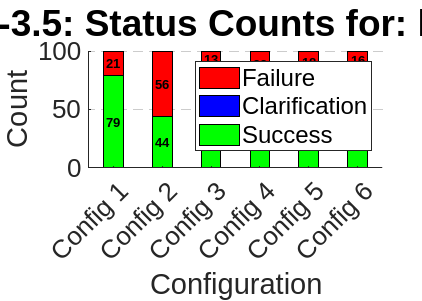

folderPath_kitchen = fullfile(go_to_area_function_folder,'kitchen');
column_kitchen = 'Results';


plotStatusCounts(folderPath_kitchen,column_kitchen)

### "Office"

Taking a look at the result it is seen it often think it is "workshop" that the user is referring to. Looking at the input it often makes sense that it might end up confuse as a human probably also going to misunderstand the request. 

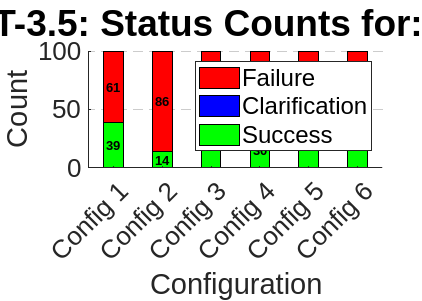

% Define the directory where the CSV files are stored
folderPath_office = fullfile(go_to_area_function_folder,'office');
column_office = 'Results';


plotStatusCounts(folderPath_office,column_office)


### "Bed Room"

text

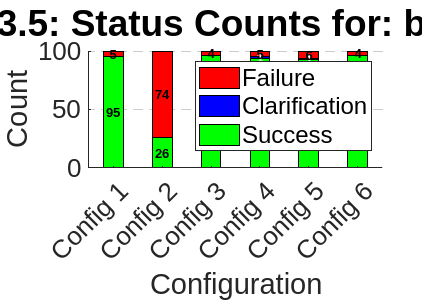

% Define the directory where the CSV files are stored
folderPath_bedroom = fullfile(go_to_area_function_folder,'bedroom');
column_bedroom = 'Results';


plotStatusCounts(folderPath_bedroom,column_bedroom)

### "Living Room"

text

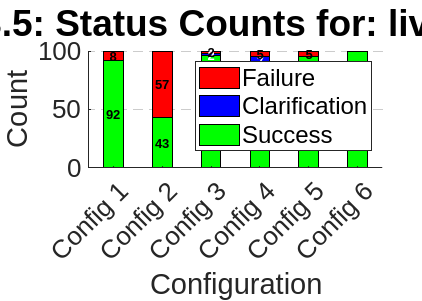

% Define the directory where the CSV files are stored
folderPath_living_room = fullfile(go_to_area_function_folder,'livingroom');
column_living_room = 'Results';


plotStatusCounts(folderPath_living_room,column_living_room)

### "Dining Room"

text

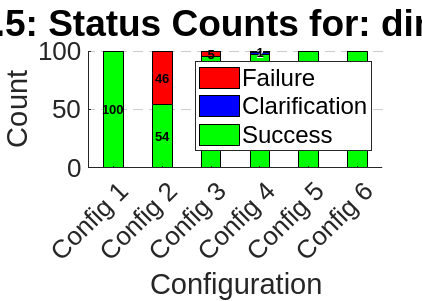

% Define the directory where the CSV files are stored
folderPath_dining_room = fullfile(go_to_area_function_folder,'diningroom');
column_dining_room = 'Results';


plotStatusCounts(folderPath_dining_room,column_dining_room)

### "Workshop"

text

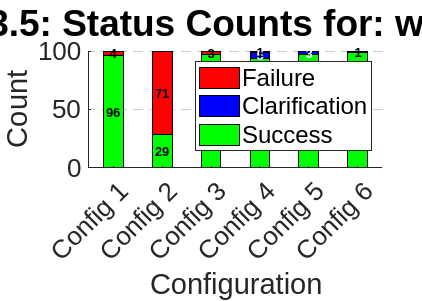

% Define the directory where the CSV files are stored
folderPath_workshop = fullfile(go_to_area_function_folder,'workshop');
column_workshop = 'Results';


plotStatusCounts(folderPath_workshop,column_workshop)

### "Garden"

text

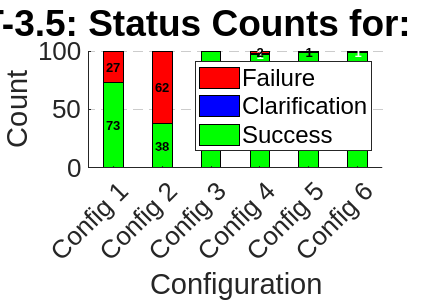

% Define the directory where the CSV files are stored
folderPath_garden = fullfile(go_to_area_function_folder,'garden');
column_garden = 'Results';


plotStatusCounts(folderPath_garden,column_garden)

### "Garage"

text

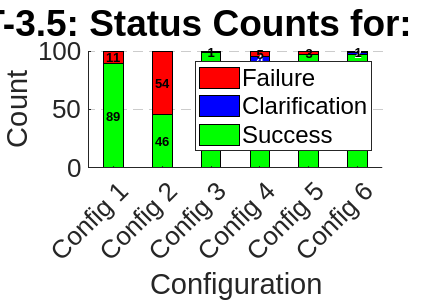

% Define the directory where the CSV files are stored
folderPath_garage = fullfile(go_to_area_function_folder,'garage');
column_garage = 'Results';


plotStatusCounts(folderPath_garage,column_garage)

### "Home"

text

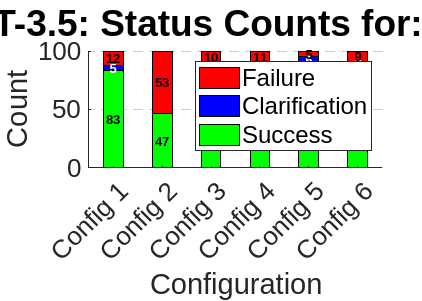

% Define the directory where the CSV files are stored
folderPath_home = fullfile(go_to_area_function_folder,'home');
column_home = 'Results';


plotStatusCounts(folderPath_home,column_home)

### "Fake Samples"

text

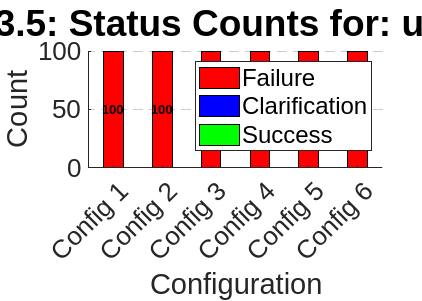

% Define the directory where the CSV files are stored
folderPath_fake_samples = fullfile(go_to_area_function_folder,'unknown');
column_location_fake_samples = 'Results';


plotStatusCounts(folderPath_fake_samples,column_location_fake_samples)

### All together in one

text

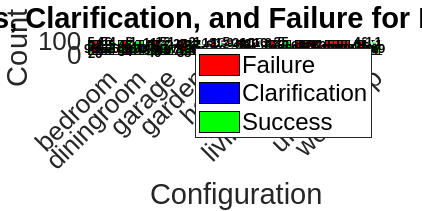

%targetStringsMap = containers.Map({'Kitchen', 'Office', 'Bedroom','Living_room','Dining_room','Workshop','Garden','Garage','Home','Fake_samples'},{targetString_kitchen,targetString_office, targetString_bedroom,targetString_living_room,targetString_dining_room,targetString_workshop, targetString_garden, targetString_garage, targetString_home,targetString_location_fake_samples});
% generateOverviewPlot(go_to_area_function_folder, 'Results', targetStringsMap);

goalAreas = {'["goal_area":"Kitchen"]', '["goal_area":"Workshop"]'};

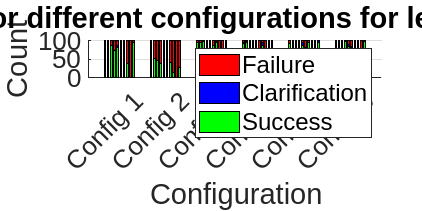

plotAllGoalAreas(go_to_area_function_folder);

plotConfigurations(go_to_area_function_folder);

## Locate_object function

Below are the result for running

locate_object_function_folder = '/home/rasmus/Desktop/Master/MasterThesisGit/final_tests/abstraction_tests/Test_results/GPT3/Sorted_for_matlab/Level01/locate_object';

### "Apple"

text

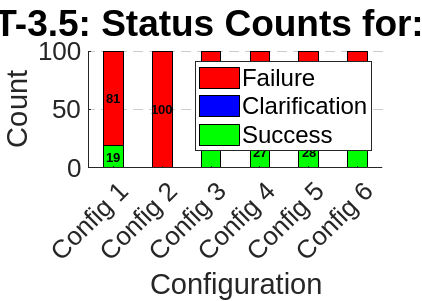

folderPath_apple = fullfile(locate_object_function_folder,'apple');
column_apple = 'Results';

plotStatusCounts(folderPath_apple,column_apple)

### "Banana"

text

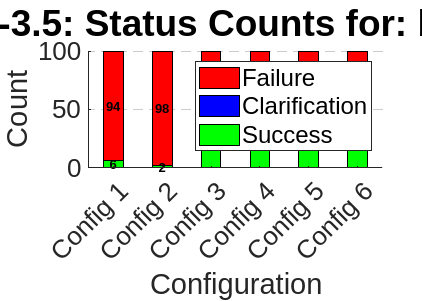

% Define the directory where the CSV files are stored
folderPath_banana = fullfile(locate_object_function_folder,'banana');
column_banana = 'Results';

plotStatusCounts(folderPath_banana,column_banana)

### "Bottle"

There exist no result for config1, hence commented out here

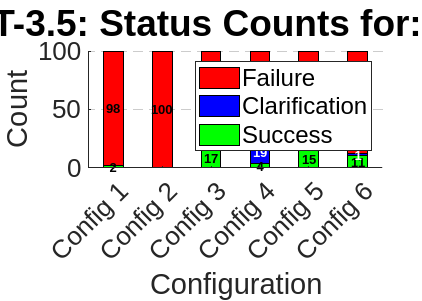

% Define the directory where the CSV files are stored
folderPath_bottle = fullfile(locate_object_function_folder,'bottle');
column_bottle = 'Results';

plotStatusCounts(folderPath_bottle,column_bottle)

### "Bowl"

text

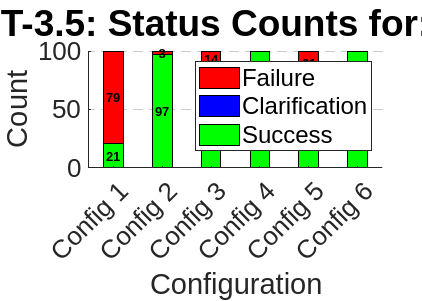

% Define the directory where the CSV files are stored
folderPath_bowl = fullfile(locate_object_function_folder,'bowl');
column_bowl = 'Results';

plotStatusCounts(folderPath_bowl,column_bowl)

### "Cat"

text

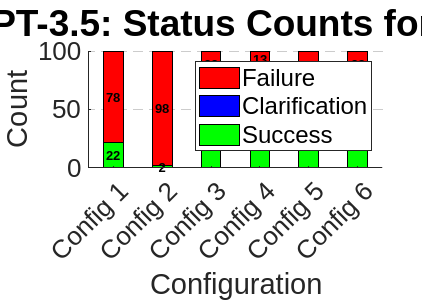

% Define the directory where the CSV files are stored
folderPath_cat = fullfile(locate_object_function_folder,'cat');
column_cat = 'Results';

plotStatusCounts(folderPath_cat,column_cat)

### "Cup"

text

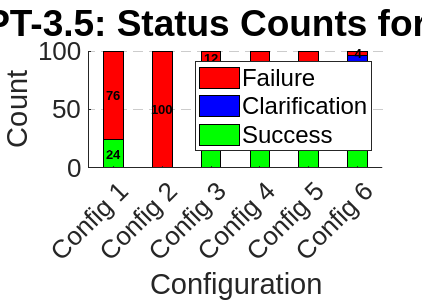

% Define the directory where the CSV files are stored
folderPath_cup = fullfile(locate_object_function_folder,'cup');
column_cup = 'Results';

plotStatusCounts(folderPath_cup,column_cup)

### "Dog"

text

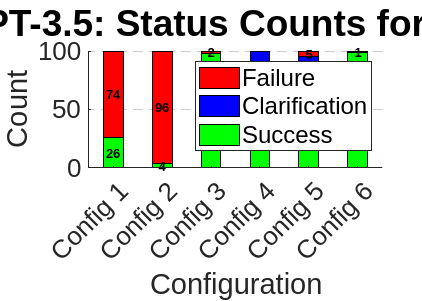

% Define the directory where the CSV files are stored
folderPath_dog = fullfile(locate_object_function_folder,'dog');
column_dog = 'Results';

plotStatusCounts(folderPath_dog,column_dog)

### "Laptop"

text

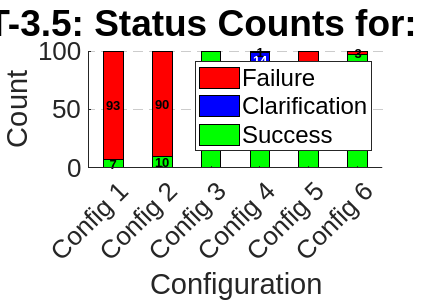

% Define the directory where the CSV files are stored
folderPath_laptop = fullfile(locate_object_function_folder,'laptop');
column_laptop = 'Results';

plotStatusCounts(folderPath_laptop,column_laptop)

### "Person"

text

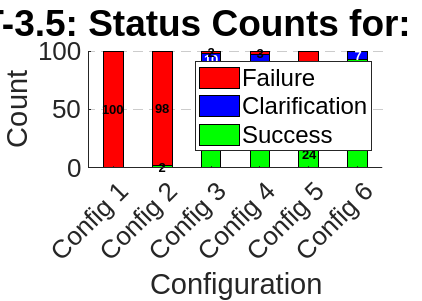

% Define the directory where the CSV files are stored
folderPath_person = fullfile(locate_object_function_folder,'person');
column_person = 'Results';

plotStatusCounts(folderPath_person,column_person)

### "Refrigerator"

text

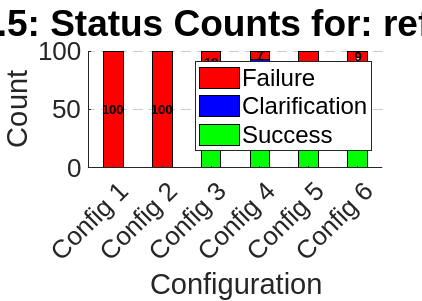

% Define the directory where the CSV files are stored
folderPath_refrigerator = fullfile(locate_object_function_folder,'refrigerator');
column_refrigerator = 'Results';

plotStatusCounts(folderPath_refrigerator,column_refrigerator)

### "Teddy bear"

text

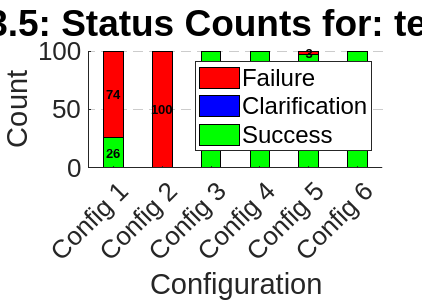

% Define the directory where the CSV files are stored
folderPath_teddy_bear = fullfile(locate_object_function_folder,'teddybear');
column_teddy_bear = 'Results';

plotStatusCounts(folderPath_teddy_bear,column_teddy_bear)

### "Fake Samples"

text

% Define the directory where the CSV files are stored
%folderPath_fake_samples = fullfile(locate_object_function_folder,'unknown');
%column_object_fake_samples = 'Results';

%plotStatusCounts(folderPath_fake_samples,column_object_fake_samples)

### All together in one

text

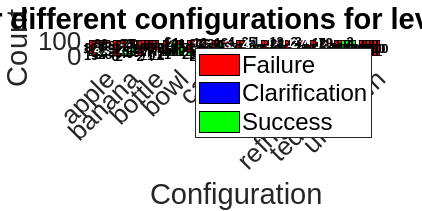

% targetStringsMap = containers.Map({'Kitchen', 'Office', 'Bedroom','Living_room','Dining_room','Workshop','Garden','Garage','Home','Fake_samples'},{targetString_kitchen,targetString_office, targetString_bedroom,targetString_living_room,targetString_dining_room,targetString_workshop, targetString_garden, targetString_garage, targetString_home,targetString_location_fake_samples});
% generateOverviewPlot(go_to_area_function_folder, 'Results', targetStringsMap);

plotAllLocateObject(locate_object_function_folder);

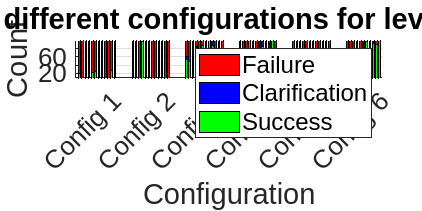

plotLocateConfigurations(locate_object_function_folder);

## Question/Answer function

Below are the result for running

## Old code might need

% % Load the CSV file
% file_name_1kitchen ='/home/rasmus/Desktop/Master/MasterThesisGit/standalone_tests/ChatGPT/Test_results/Prompt_config1/01kitchen_commands.csv';
% 
% % Preparing data
% column = 'Results';
% targetString = "['{""goal_area"":""Kitchen""}']";
% targetString2 = "['{""goal_area"":""Bed Room""}']";
% [successCount, failureCount] = countSuccessFailure(file_name_1kitchen, column, targetString);
% 
% fprintf('Success count: %d\n', successCount);
% fprintf('Failure count: %d\n', failureCount);
% 
% % Calculate the percentage of success and failure
% percentageSuccess = (successCount / (successCount + failureCount)) * 100;
% percentageFailure = (failureCount / (successCount + failureCount)) * 100;
% 
% % Define colors for the bars
% colorSuccess = [0.2, 0.7, 0.3]; % Green
% colorFailure = [0.9, 0.2, 0.1]; % Red
% 
% % Create a bar plot with failure bars stacked on top of success bars
% categories = {'Kitchen'};
% bar(1, [percentageSuccess, percentageFailure], 'stacked');
% 
% % Set colors for each segment of the bar
% colormap([colorSuccess; colorFailure]);
% 
% text(1, percentageSuccess/2, sprintf('%.2f%%', percentageSuccess), ...
%     'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Color', 'white');
% text(1, percentageSuccess + percentageFailure/2, sprintf('%.2f%%', percentageFailure), ...
%     'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Color', 'white');
% 
% % Set labels and title
% set(gca, 'XTickLabel', categories);
% xlabel('Outcome');
% ylabel('Success / Failure');
% title('Success rate');
% 
% % Set y-axis limits
% ylim([0 100]);
% 
% filename1 = '/home/rasmus/Desktop/Master/MasterThesisGit/standalone_tests/ChatGPT/Test_results/Prompt_config1/01kitchen_commands.csv';
% filename2 = '/home/rasmus/Desktop/Master/MasterThesisGit/standalone_tests/ChatGPT/Test_results/Prompt_config1/01bedroom_commands.csv';
% filename3 = '/home/rasmus/Desktop/Master/MasterThesisGit/standalone_tests/ChatGPT/Test_results/Prompt_config1/01kitchen_commands.csv';
% 
% % Call the function to get counts for each experiment
% [countSuccess1, countFailure1] = countSuccessFailure(filename1, column, targetString);
% [countSuccess2, countFailure2] = countSuccessFailure(filename2, column, targetString2);
% [countSuccess3, countFailure3] = countSuccessFailure(filename3, column, targetString);
% 
% % Define colors for the bars
% colorSuccess = [0 0 1]; % Blue for success
% colorFailure = [1 0 0]; % Red for failure
% 
% % Set the width of the bars here (between 0 and 1)
% barWidth = 0.4; % Smaller value for thinner bars
% 
% xPositions = 1:3;
% 
% % Create grouped bar graph
% fig = figure;
% b = bar(xPositions, [[countSuccess1 countFailure1]; [countSuccess2 countFailure2]; [countSuccess3 countFailure3]],barWidth, 'stacked');
% 
% % After plotting the success, plot failure on top to create stacked effect
% % The first bar object corresponds to success
% set(b(1), 'FaceColor', colorSuccess);
% % The second bar object corresponds to failure
% set(b(2), 'FaceColor', colorFailure);
% 
% % Add text labels for each success and failure value
% for i = 1:length(xPositions)
%     % Text for success count
%     successText = num2str(b(1).YData(i));
%     text(i, b(1).YData(i)/2, successText, 'HorizontalAlignment', 'center', 'Color', 'white','FontWeight', 'bold');
% 
%     % Text for failure count, displayed above the success count
%     if b(2).YData(i) > 0
%         failureText = num2str(b(2).YData(i));
%         text(i, b(1).YData(i) + b(2).YData(i)/2, failureText, 'HorizontalAlignment', 'center', 'Color', 'white','FontWeight', 'bold');
%     end
% end
% 
% % Add legend
% legend({'Success', 'Failure'}, 'Location', 'NorthEast');
% 
% % Set labels and title
% xlabel('Configuration');
% ylabel('Count');
% title('Success and Failure Rates for Different Configurations');
% 
% % Set x-axis limits and ticks
% xlim([0.5, 3.5]);
% xticks(xPositions);
% xticklabels({'Config-1', 'Config-2', 'Config-3'});
% 
% % Show the figure
% %set(fig, 'Visible', 'on');
% % Define the directory where the CSV files are stored
% %folderPath_kitchen = '/home/rasmus/Desktop/Master/MasterThesisGit/standalone_tests/ChatGPT/Test_results/Test';